## part 1: introduction to matlab


$$y = cos(2\pi ft)$$


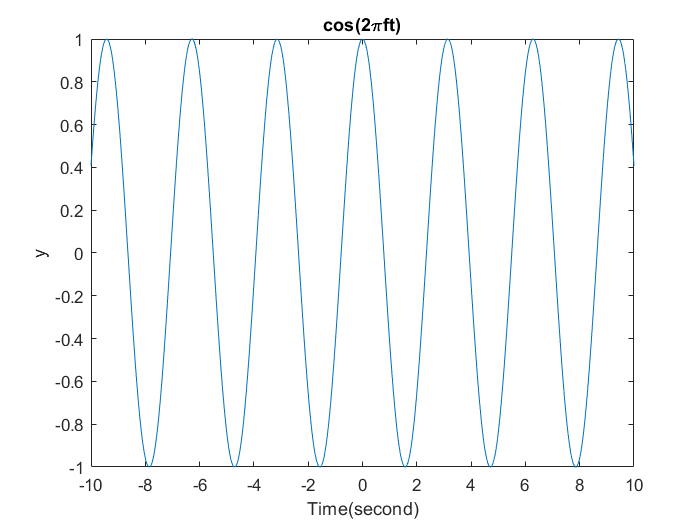

time_step = 0.001;
fs = 1/time_step;
f = 1/pi;
t = -10:time_step:10;
y = cos(2*pi.*f*t);

plot(t, y)
title cos(2\pift) 
ylabel y
xlabel Time(second)
xlim( [-10  10])

## Fourier transform of cos(x)

n = length(y);
ff = linspace(-fs/2, fs/2, numel(y))

ff =  -500.0000 -499.9500 -499.9000 -499.8500 -499.8000 -499.7500 -499.7000 -499.6500 -499.6000 -499.5500 -499.5000 -499.4500 -499.4000 -499.3500 -499.3000 -499.2500 -499.2000 -499.1500 -499.1000 -499.0500 -499.0000 -498.9500 -498.9000 -498.8500 -498.8000 -498.7500 -498.7000 -498.6500 -498.6000 -498.5500 -498.5000 -498.4500 -498.4000 -498.3500 -498.3000 -498.2500 -498.2000 -498.1500 -498.1000 -498.0500 -498.0000 -497.9500 -497.9000 -497.8500 -497.8000 -497.7500 -497.7000 -497.6500 -497.6000 -497.5500


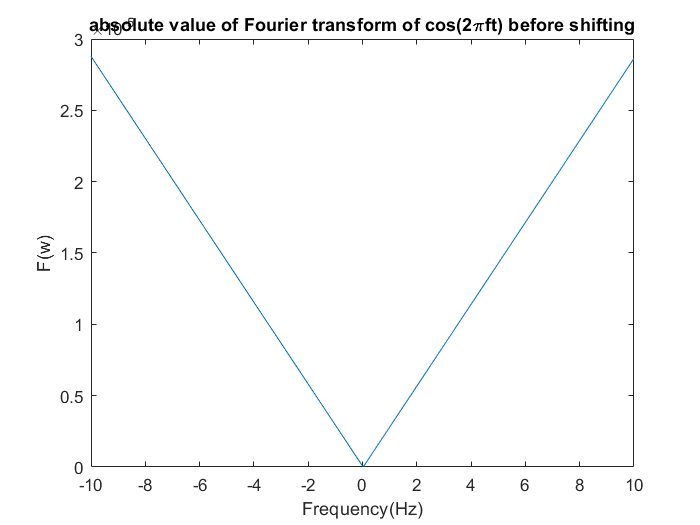

yff = fft(y);
plot(ff, abs(yff))
xlim( [-10  10])
title 'absolute value of Fourier transform of cos(2\pift) before shifting'
xlabel Frequency(Hz)
ylabel F(w)


yshift = fftshift(yff)

yshift = 	1.0e+03 *

  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i


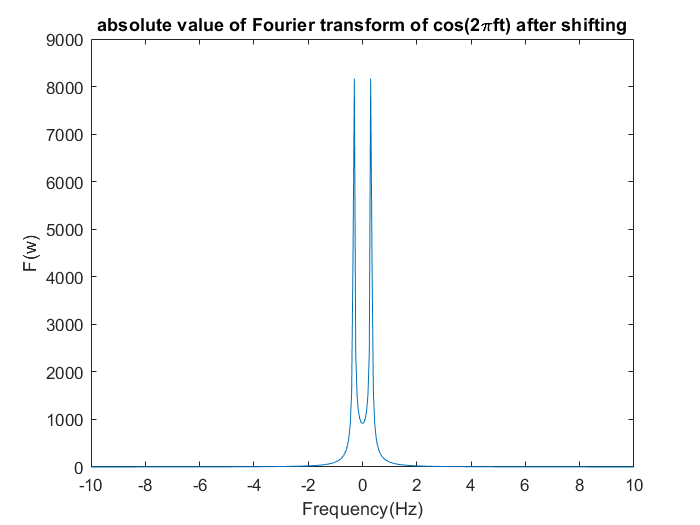

plot(ff, abs(yshift))
xlim( [-10  10])
title 'absolute value of Fourier transform of cos(2\pift) after shifting'
xlabel Frequency(Hz)
ylabel F(w)

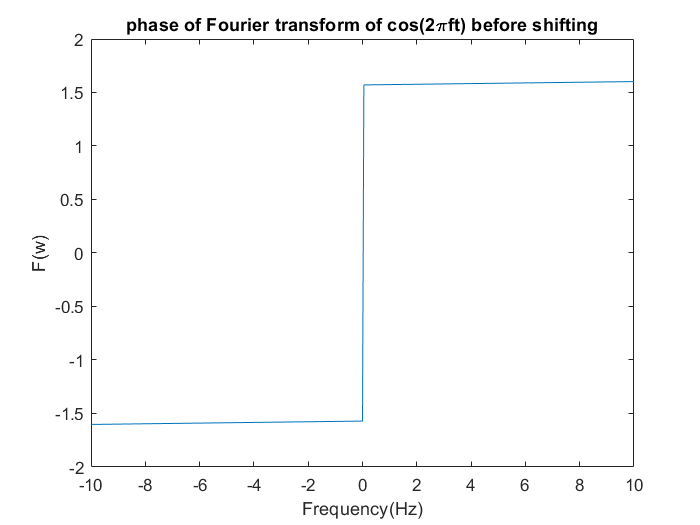


plot(ff, angle(yff))
xlim( [-10  10])
title 'phase of Fourier transform of cos(2\pift) before shifting'
xlabel Frequency(Hz)
ylabel F(w)

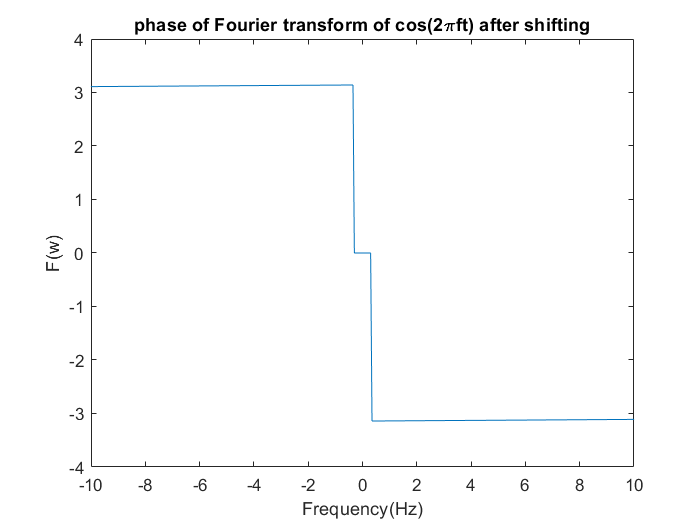


plot(ff, angle(yshift))
xlim( [-10  10])
title 'phase of Fourier transform of cos(2\pift) after shifting'
xlabel Frequency(Hz)
ylabel F(w)

## part 2-Sleep status processing

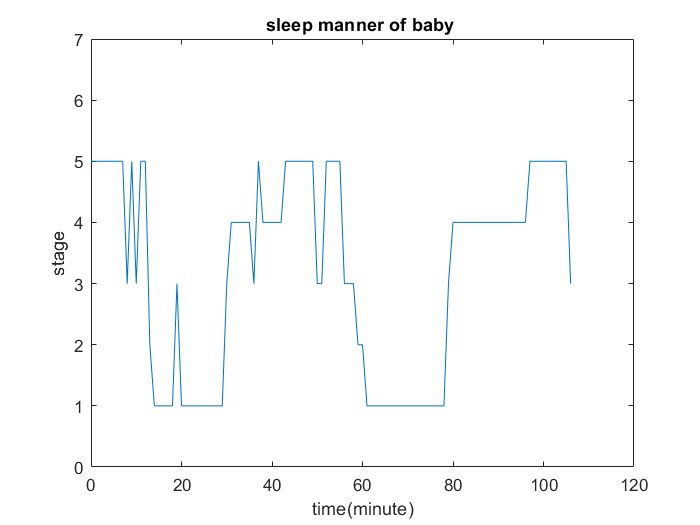

%1
name = 'data.mat';
sleep_manner = importdata(name);
sleep_manner = categorical(sleep_manner);
sleep_manner = renamecats(sleep_manner,{ 'qt', 'qh', 'tr' , 'al' , 'ah'}, {'1', '2', '3', '4', '5' });
sleep_manner = str2double(string(sleep_manner));
time_step = 1;
t = 0:time_step:106;
plot(t, sleep_manner)
ylim([0 7]);
title 'sleep manner of baby '
xlabel time(minute)
ylabel stage



fss = 60;
fftt = linspace(-fss/2, fss/2, 107)

fftt =   -30.0000  -29.4340  -28.8679  -28.3019  -27.7358  -27.1698  -26.6038  -26.0377  -25.4717  -24.9057  -24.3396  -23.7736  -23.2075  -22.6415  -22.0755  -21.5094  -20.9434  -20.3774  -19.8113  -19.2453  -18.6792  -18.1132  -17.5472  -16.9811  -16.4151  -15.8491  -15.2830  -14.7170  -14.1509  -13.5849  -13.0189  -12.4528  -11.8868  -11.3208  -10.7547  -10.1887   -9.6226   -9.0566   -8.4906   -7.9245   -7.3585   -6.7925   -6.2264   -5.6604   -5.0943   -4.5283   -3.9623   -3.3962   -2.8302   -2.2642


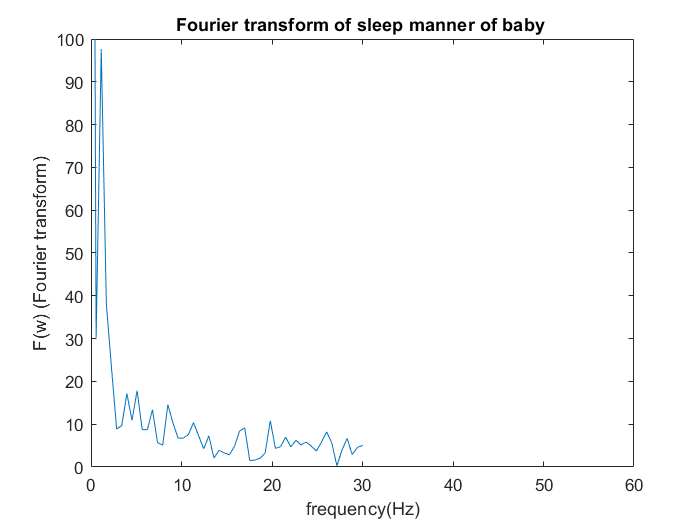

yfftt = fft(sleep_manner);
yshiftt = fftshift(yfftt);
plot(fftt, abs(yshiftt));
title 'Fourier transform of sleep manner of baby '
ylabel 'F(w) (Fourier transform)'
xlabel frequency(Hz)
xlim([0 60])
ylim([0 100])



%2
sleep_manner = importdata(name)

sleep_manner = 1×107 cell array
    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'tr'}    {'ah'}    {'tr'}    {'ah'}    {'ah'}    {'qh'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'tr'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'tr'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'tr'}    {'ah'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'tr'}    {'tr'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'tr'}    {'tr'}    {'tr'}    {'qh'}    {'qh'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'tr'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al

sleep_manner = categorical(sleep_manner);
sleep_manner = renamecats(sleep_manner,{'qt', 'qh', 'tr' , 'al' , 'ah'}, {'5', '3', '2', '4', '1' });
sleep_manner = str2double(string(sleep_manner))

sleep_manner =      1     1     1     1     1     1     1     1     2     1     2     1     1     3     5     5     5     5     5     2     5     5     5     5     5     5     5     5     5     5     2     4     4     4     4     4     2     1     4     4     4     4     4     1     1     1     1     1     1     1


fss = 60;
fftt = linspace(-fss/2, fss/2, 107)

fftt =   -30.0000  -29.4340  -28.8679  -28.3019  -27.7358  -27.1698  -26.6038  -26.0377  -25.4717  -24.9057  -24.3396  -23.7736  -23.2075  -22.6415  -22.0755  -21.5094  -20.9434  -20.3774  -19.8113  -19.2453  -18.6792  -18.1132  -17.5472  -16.9811  -16.4151  -15.8491  -15.2830  -14.7170  -14.1509  -13.5849  -13.0189  -12.4528  -11.8868  -11.3208  -10.7547  -10.1887   -9.6226   -9.0566   -8.4906   -7.9245   -7.3585   -6.7925   -6.2264   -5.6604   -5.0943   -4.5283   -3.9623   -3.3962   -2.8302   -2.2642


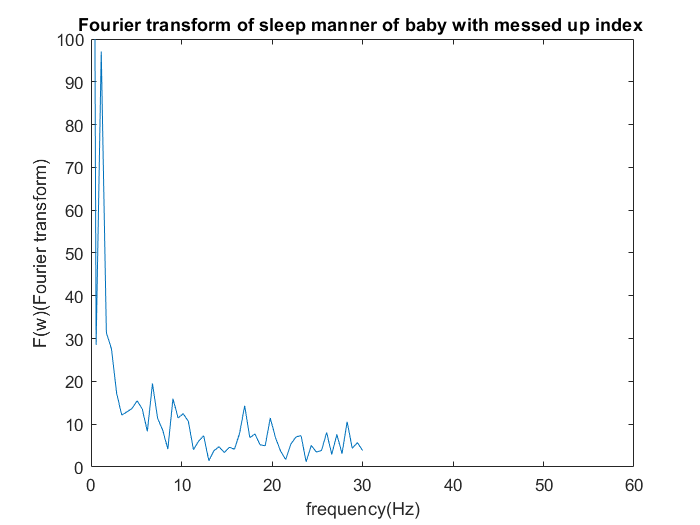

yfftt = fft(sleep_manner);
yshiftt = fftshift(yfftt);
plot(fftt, abs(yshiftt));
title 'Fourier transform of sleep manner of baby with messed up index '
xlabel frequency(Hz)
ylabel 'F(w)(Fourier transform)'
xlim([0 60])
ylim([0 100])


%3
sleep_manner = importdata(name)

sleep_manner = 1×107 cell array
    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'tr'}    {'ah'}    {'tr'}    {'ah'}    {'ah'}    {'qh'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'tr'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'tr'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'tr'}    {'ah'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'tr'}    {'tr'}    {'ah'}    {'ah'}    {'ah'}    {'ah'}    {'tr'}    {'tr'}    {'tr'}    {'qh'}    {'qh'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'qt'}    {'tr'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al'}    {'al

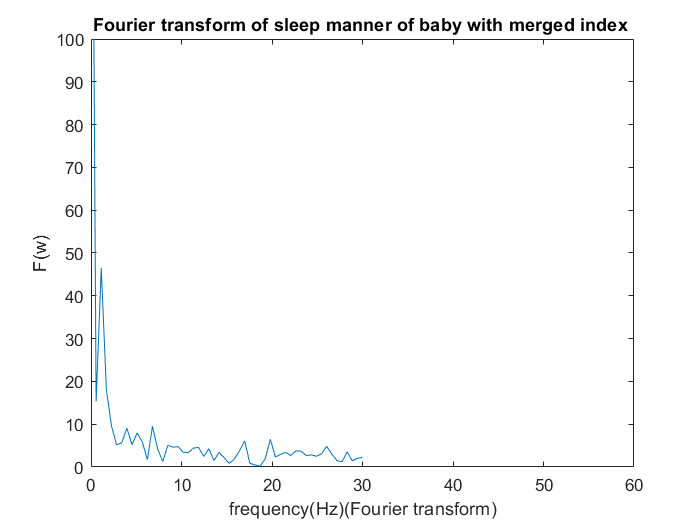

sleep_manner = categorical(sleep_manner);
sleep_manner(sleep_manner == 'tr') = 'al';
sleep_manner(sleep_manner == 'qt') = 'qh';
sleep_manner = renamecats(sleep_manner,{'qh', 'al' , 'ah'}, {'1', '2', '3' });
sleep_manner = str2double(string(sleep_manner));
fss = 60;
fftt = linspace(-fss/2, fss/2, 107);
yfftt = fft(sleep_manner);
yshiftt = fftshift(yfftt);
plot(fftt, abs(yshiftt));
title 'Fourier transform of sleep manner of baby with merged index '
xlabel 'frequency(Hz)(Fourier transform)'
ylabel F(w)
xlim([0 60])
ylim([0 100])

## part 3 - music

[y1, Fs1] = audioread('piano_A.mp3');
[y2, Fs2] = audioread('piano_A_sharp.mp3');
[y3, Fs3] = audioread('piano_B.mp3');
[y4, Fs4] = audioread('piano_C_sharp.mp3');
[y5, Fs5] = audioread('piano_D.mp3');
[y6, Fs6] = audioread('piano_D_sharp.mp3');
[y7, Fs7] = audioread('piano_E.mp3');
[y8, Fs8] = audioread('piano_F.mp3');
[y9, Fs9] = audioread('piano_F_sharp.mp3');
[y10, Fs10] = audioread('piano_G.mp3');
[y11, Fs11] = audioread('piano_G_sharp.mp3');
[y12, Fs12] = audioread('piano_middle_C.mp3');


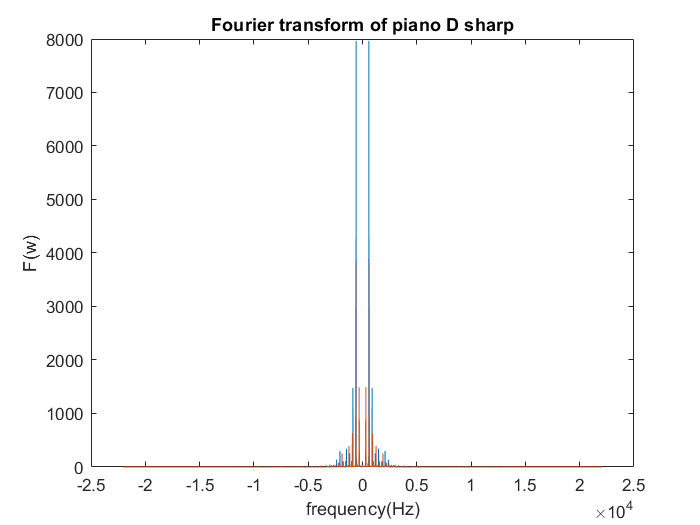

n5 = length(y5);
FFs5 = (-n5/2:n5/2-1)*(Fs5/n5);
y55 = fft(y5);
ysh5 = fftshift(y55);
plot(FFs5, abs(ysh5));
title 'Fourier transform of piano D'
xlabel frequency(Hz)
ylabel F(w)
hold on
n6 = length(y6);
FFs6 = (-n6/2:n6/2-1)*(Fs6/n6);
y66 = fft(y6);
ysh6 = fftshift(y66);
plot(FFs6, abs(ysh6));
title 'Fourier transform of piano D sharp'
xlabel frequency(Hz)
ylabel F(w)
hold off

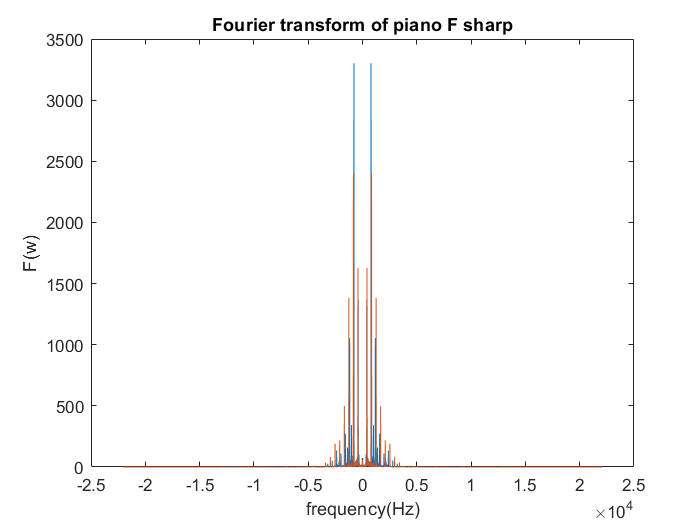


n10 = length(y10);
FFs10 = (-n10/2:n10/2-1)*(Fs10/n10);
y1010 = fft(y10);
ysh10 = fftshift(y1010);
plot(FFs10, abs(ysh10));
title 'Fourier transform of piano F'
xlabel frequency(Hz)
ylabel F(w)
hold on
n11 = length(y11);
FFs11 = (-n11/2:n11/2-1)*(Fs11/n11);
y1111= fft(y11);
ysh1111 = fftshift(y1111);
plot(FFs11, abs(ysh1111));
title 'Fourier transform of piano F sharp'
xlabel frequency(Hz)
ylabel F(w)
hold off

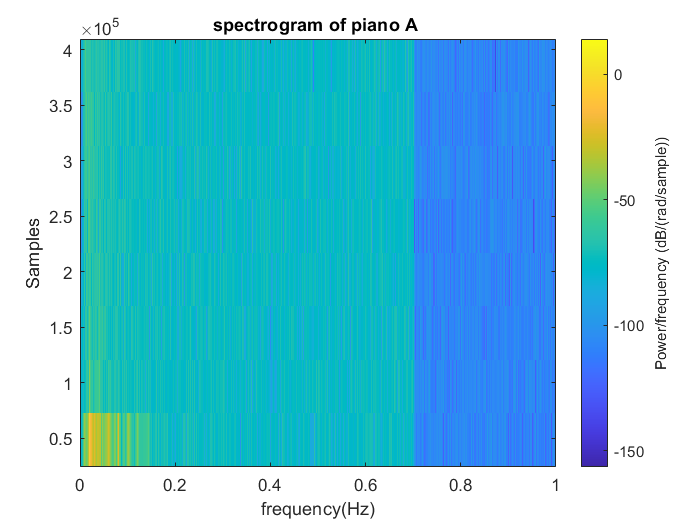



sound(y5, Fs5)
sound(y6, Fs6)

%spectrogram for y1 and y2
spectrogram(y1)
title 'spectrogram of piano A '
xlabel frequency(Hz)

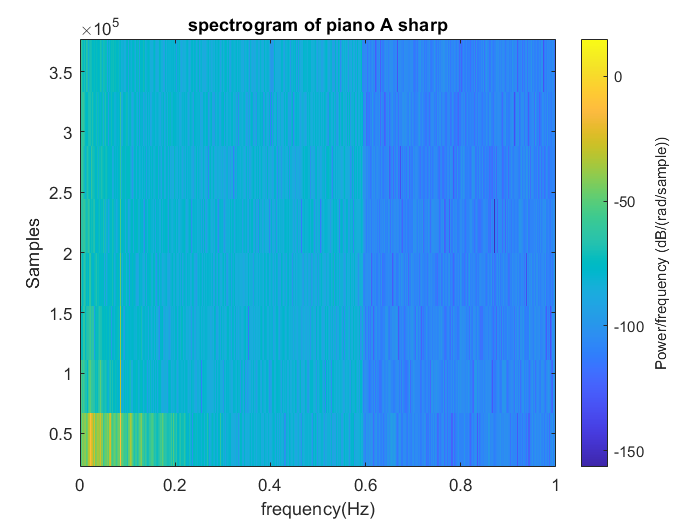


spectrogram(y2)
title 'spectrogram of piano A sharp'
xlabel frequency(Hz)